clear all; clc;
% cd(fileparts(which(mfilename)));  % In a .m file uncomment this
cd(fileparts(matlab.desktop.editor.getActiveFilename)); % In a .mlx file uncomment this

# Example: Parabolic Launch in the Moon (Free Particle Gravity 2D)

To develop a Kalman filter to track of a particle in a parabolic launch at the moon (no atmosphere, $g=1.622\frac{m}{s^2}$).

The GPS sensor that can be used to measure the particle position have an error of $\pm 1 m$.

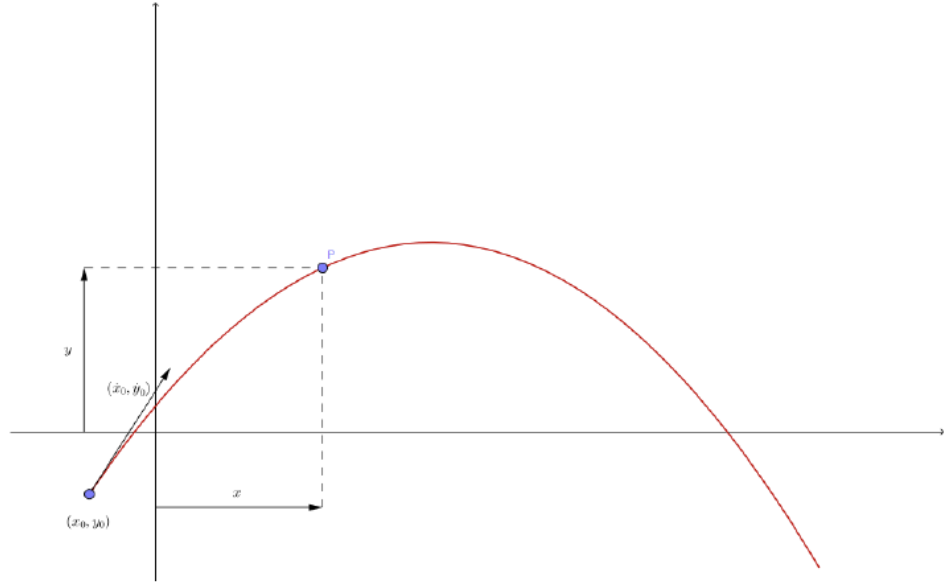

# Solution:

## Parameters and initial state definition

global t t_0 t_end Delta_t
global mu_x Sigma2_x
global u_meas z_meas
global sigma_u_actual sigma_z_actual x_actual x_actual_0 u_actual_func rng_status seed
global x_string u_string z_string
global param

Define actual handle to function determining the input

u_actual_func = @(t) my_u_actual_func(t);

Seed to get repeatable results between runs (particularly important for ML estimation)

seed=1789; rng(seed);
rng_status=rng;

Set initial time $t_0$, sampling frequency $\Delta t$ and final simulation time $t_{end}$

t_0=0;         		    %s
Delta_t=0.01;           %s
t_end=50;               %s

Define model parameters

m=1;          %kg
g=1.622;      %m/s^2

param=[m g Delta_t ]'; % as is from main_symbolic_EKF.m

Set deterministic true/actual system Initial state $\mathbf{x}_0^{tr}$

x_0=-2; %m
y_0=-1; %m
dx_0=4; %m/s
dy_0=4; %m/s

q_0=[x_0,y_0]';
dq_0=[dx_0,dy_0]';

x_actual_0=[q_0;dq_0];

Filter Initial state and variance $\mu_{x_0}$, $\sigma_{x_0}^2$, estimated from limits in historical meassurements

% Initial mu_x covariance
delta_x0=3 * 1;  % m no idea at all
delta_y0=3 * 1;  % m no idea at all
delta_dx0=20;    % m/s no idea at all
delta_dy0=20;    % m/s no idea at all
sigma_x_0= [ delta_x0, delta_y0, delta_dx0, delta_dy0]';

mu_x_0 = x_actual_0+sigma_x_0;
Sigma2_x_0 = diag(sigma_x_0.^2); % assumed diagonal

Model equation error variance $\sigma^2_{u_{k}}$ and $\sigma^2_{w_k}$

n_u=size(u_actual_func(t_0),1);
sigma_u_actual=[];
sigma_u=[];

The second order tailor expansion of $\mathbf{q}_{k+1}=\mathbf{q}_{k}+\frac{1}{1!}\dot{\mathbf{q}}_{k}\Delta t+\frac{1}{2!}\left[\begin{array}{c}0\\-g\end{array}\right](\Delta t)^2$ and $\dot{\mathbf{q}}_{k+1}=\dot{\mathbf{q}}_{k}+\frac{1}{1!}\left[\begin{array}{c}0\\-g\end{array}\right]\Delta t$ are exact. Our Euler discretization assumes $\mathbf{q}_{k+1}=\mathbf{q}_{k}+\frac{1}{1!}\dot{\mathbf{q}}_{k}\Delta t$ and $\dot{\mathbf{q}}_{k+1}=\dot{\mathbf{q}}_{k}+\frac{1}{1!}\left[\begin{array}{c}0\\-g\end{array}\right]\Delta t$ and therefore the error in discterization is $\frac{1}{2!}\left[\begin{array}{c}0\\-g\end{array}\right](\Delta t)^2$ at the level of coordinates and $\mathbf0}$ at the level of generalized velocities.

sigma_discr=([0,1/2*g*Delta_t^2,0,0])';

Parameters for other noise sources in process equation $\mathbf{w}_{k}$.  Process equation error std $\mathbf{\sigma}_{\mathbf{w}_{k}}$.

n_x=size(x_actual_0,1);
sigma_w_x=zeros([n_x,1]);

Sensor equation error std $\mathbf{\sigma}_{\mathbf{z}_{k+1}}$, and input sensor measurement error std $\mathbf{\sigma}_{\mathbf{u}_{k}}$ can be given based on the specification sheet of the sensors used to measure $\mathbf{z}$ and $\mathbf{u}$ and are used to tune the filter (use a better value if your have one available). $\mathbf{\sigma}_{\mathbf{z}_{k+1}}^{tr}$ and $\mathbf{\sigma}_{\mathbf{u}_{k}}^{tr}$ are the ***actual*** values of the error std for the sensors used to measure $\mathbf{z}$ and $\mathbf{u}$.

sigma_GPS_x=1; % 1 m seems reasonable error for GPS
sigma_GPS_z=1; % 1 m seems reasonable error for GPS

sigma_GPS_x_spec=sigma_GPS_x;
sigma_GPS_z_spec=sigma_GPS_z;

sigma_z_actual=[sigma_GPS_x,sigma_GPS_z]';
sigma_z=[sigma_GPS_x_spec,sigma_GPS_z_spec]';

Parameters for other noise sources in sensor equation $\mathbf{v}_{k+1}$. Sensor equation error std $\mathbf{\sigma}_{\mathbf{v}_{k+1}}$.

n_z=size(sigma_z_actual,1);
sigma_v_x=zeros(n_z,1);

Set variable names for Plotting()

q_string=["x","y"]';
dq_string=["\dot{x}","\dot{y}"]';
x_string=[q_string;
    dq_string];
u_string=[];
z_string=["x","y"]';

Set variables for dataloging

datalogging_string={'t';'x_actual';'mu_x';'u_actual';'u_meas';'z_actual';'z_meas';'sigma_x'};

## Kalman Filter Loop

Begin filtering

fid=fopen('sol.dat','w');

Reset random number generator

rng(rng_status);

Set initial state

t=t_0;
mu_x=mu_x_0;
Sigma2_x=Sigma2_x_0;
sigma_x=sigma_x_0;

x_actual=x_actual_0;

Read

u_meas=get_u(); z_meas=get_z();

Write

datalogging(fid, datalogging_string);

Filter iteration

for k=1:t_end/Delta_t

Kalman step

    IEKF(sigma_discr, sigma_z, sigma_u,sigma_w_x,sigma_v_x);

Write 

    datalogging(fid, datalogging_string);
end

End filtering

fclose(fid);

## Observability

Linear observability near the end of the simulation

u_meas=get_u(); z_meas=get_z();
f_x_=f_x(mu_x,u_meas,t,param);
h_x_=h_x(mu_x,u_meas,t,param);

OB=obsv(f_x_,h_x_)

OB =     1.0000         0         0         0
         0    1.0000         0         0
    1.0000         0    0.0100         0
         0    1.0000         0    0.0100
    1.0000         0    0.0200         0
         0    1.0000         0    0.0200
    1.0000         0    0.0300         0
         0    1.0000         0    0.0300


rank(OB)

ans = 4

size(OB)

ans =      8     4


Nonlinear observability near the end of the simulation

load_datalogging('sol.dat', datalogging_string)

Nonlinear observabilty matrix must be bigger (more rows) than the linear one. So 5 time steps must suffice ( $5 \times 2=10>8$ )

k=length(t_series)-5;

OB=[h_x(x_actual_series(k,:)',u_meas_series(k,:)',t_series(k,:),param)
    h_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)*f_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)
    h_x(x_actual_series(k+2,:)',u_meas_series(k+2,:)',t_series(k+2,:),param)*f_x(x_actual_series(k+2,:)',u_meas_series(k+2,:)',t_series(k+2,:),param)*f_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)
    h_x(x_actual_series(k+3,:)',u_meas_series(k+3,:)',t_series(k+3,:),param)*f_x(x_actual_series(k+3,:)',u_meas_series(k+3,:)',t_series(k+3,:),param)*f_x(x_actual_series(k+2,:)',u_meas_series(k+2,:)',t_series(k+2,:),param)*f_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)
    h_x(x_actual_series(k+4,:)',u_meas_series(k+4,:)',t_series(k+4,:),param)*f_x(x_actual_series(k+4,:)',u_meas_series(k+4,:)',t_series(k+4,:),param)*f_x(x_actual_series(k+3,:)',u_meas_series(k+3,:)',t_series(k+3,:),param)*f_x(x_actual_series(k+2,:)',u_meas_series(k+2,:)',t_series(k+2,:),param)*f_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)]

OB =     1.0000         0         0         0
         0    1.0000         0         0
    1.0000         0    0.0100         0
         0    1.0000         0    0.0100
    1.0000         0    0.0200         0
         0    1.0000         0    0.0200
    1.0000         0    0.0300         0
         0    1.0000         0    0.0300
    1.0000         0    0.0400         0
         0    1.0000         0    0.0400


rank(OB)

ans = 4

clear *_series

## Real filter error statistics in the limit when $k \longrightarrow \infty$

We compute the sample mean and std for the prediction error. We consider just the last 100 samples, as for a lienar system and filter this error will become statistically stationary after some time. This statistical stationarity can be seeen in the plots. These values are plotted (as horizontal lines) along with the kalman filter predicted std of the state variables, so robustness can be ascertained.

load_datalogging('sol.dat', datalogging_string);
mu_x_error_series=mu_x_series-x_actual_series;
num_samples_statistic=100;
lim_mu_x_error=mu_x_error_series(end-num_samples_statistic:end,:);
lim_mu_x_error_mean=mean(lim_mu_x_error);
lim_mu_x_error_std=std(lim_mu_x_error);
sqrt_lim_mu_x_error_squared_mean=mean((lim_mu_x_error).^2).^0.5;

## Plotting

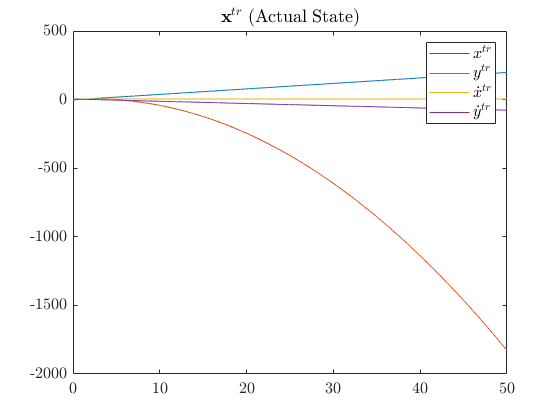

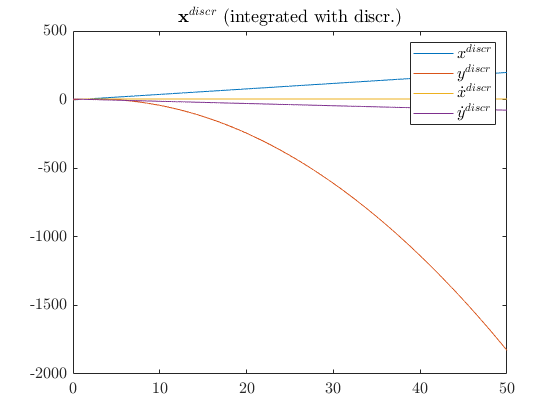

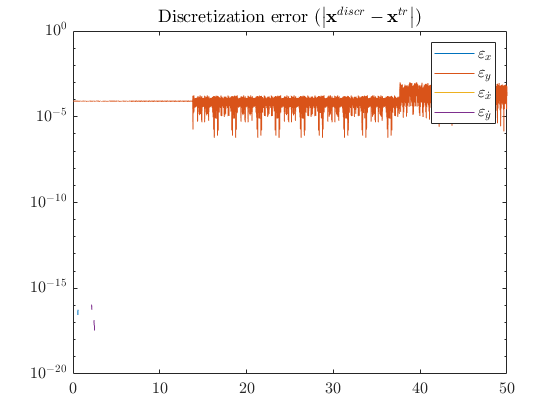

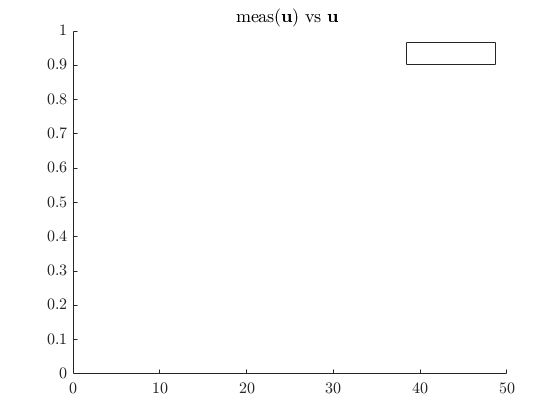

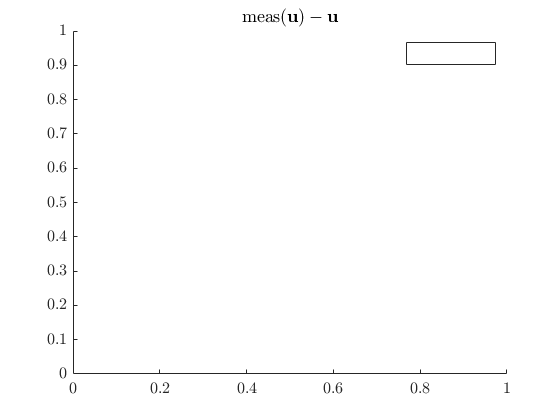

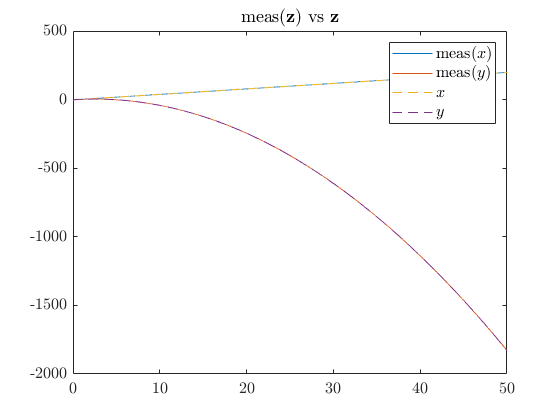

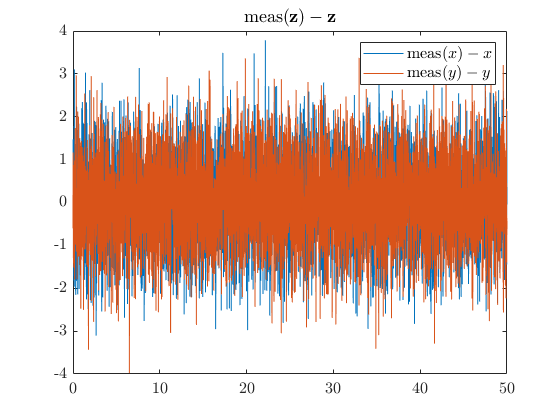

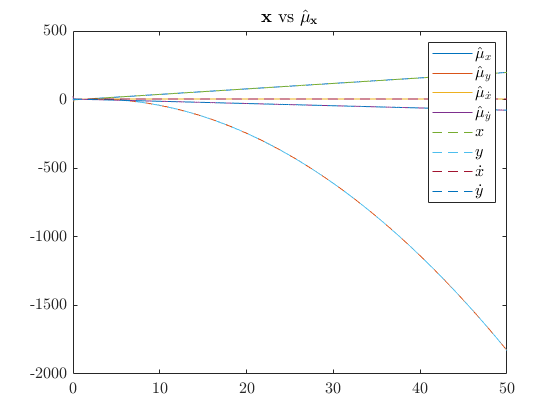

load_datalogging('sol.dat', datalogging_string);
fig_dir=['Information_EKF_',num2str(Delta_t)];
Plotting(fig_dir, datalogging_string);

## Maximum Likelihood (ML) Estimation of Filter Parameters

theta_=[sigma_discr;sigma_z]

theta_ =          0
    0.0001
         0
         0
    1.0000
    1.0000


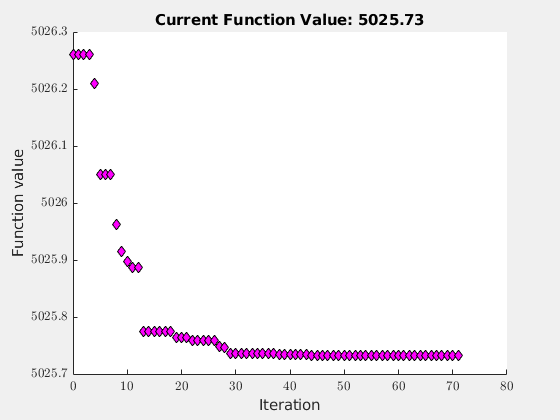

% function parameters logL_IEKF(sigma_discr,sigma_z,sigma_u,mu_x_0,sigma_x_0)
fun = @(theta_) logL_IEKF(theta_(1:4),theta_(5:6),sigma_u,sigma_w_x,sigma_v_x,mu_x_0,sigma_x_0);
options = optimset('PlotFcns',@optimplotfval);
theta_ = fminsearch(fun, theta_,options);

sigma_discr=theta_(1:n_x)

sigma_discr = 	1.0e+-4 *

    0.5463
    0.8362
   -0.0005
   -0.6333


sigma_z=theta_(n_x+1:n_x+n_z)

sigma_z =     1.0064
    0.9926


save('ML_opt','sigma_discr','sigma_z')

## Load previous Maximum Likelihood (ML) Estimation of Filter Parameters

load('ML_opt')

## Kalman Filter Iteration

Begin filtering

fid=fopen('sol.dat','w');

Reset random number generator

rng(rng_status);

Set initial state

t=t_0;
mu_x=mu_x_0;
Sigma2_x=Sigma2_x_0;
sigma_x=sigma_x_0;

x_actual=x_actual_0;

Read

u_meas=get_u();
z_meas=get_z();

Write

datalogging(fid, datalogging_string);

Filter iteration

for k=1:t_end/Delta_t

Kalman step

    IEKF(sigma_discr, sigma_z, sigma_u,sigma_w_x,sigma_v_x);

Write 

    datalogging(fid, datalogging_string);
end

End filtering

fclose(fid);

## Plotting

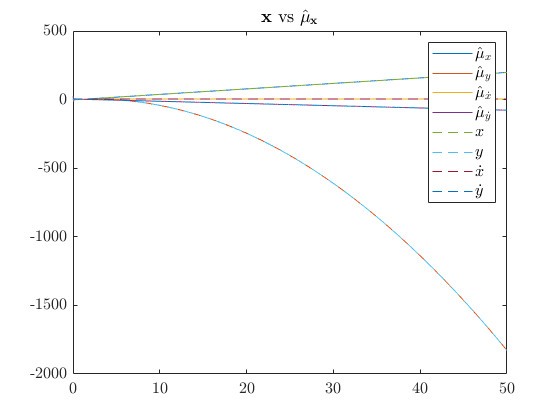

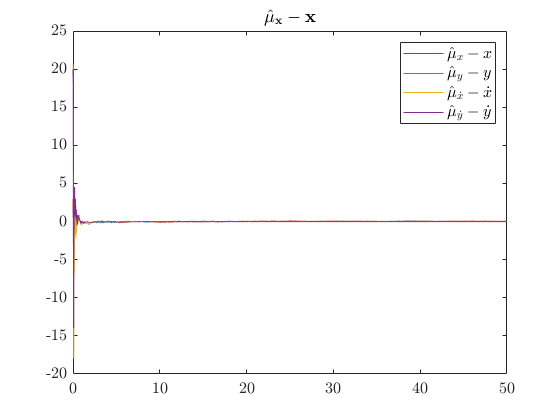

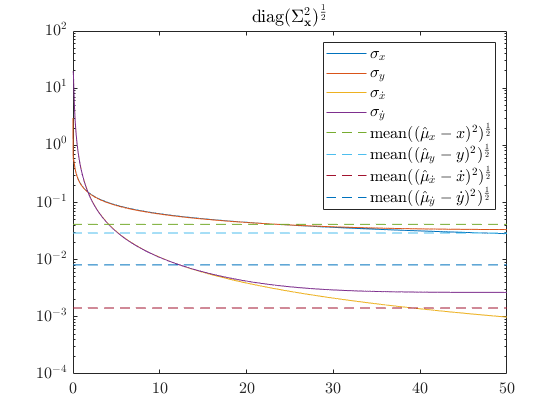

load_datalogging('sol.dat', datalogging_string);
fig_dir=['Information_EKF_',num2str(Delta_t)];
Plotting(fig_dir, datalogging_string);

## Helper functions

function logL=logL_IEKF(sigma_discr,sigma_z,sigma_u,sigma_w_x,sigma_v_x,mu_x_0,sigma_x_0)
global t t_0 t_end Delta_t
global u_meas z_meas 
global mu_x Sigma2_x
global mu_x_pred Sigma2_x_pred R
global rng_status
global param

%% Kalman Filter Loop

% Starting simulation time and length
logL=0;
%% Read Input and Sensor at first (k=1)

rng(rng_status);

t=t_0;
mu_x=mu_x_0;
Sigma2_x=diag((sigma_x_0).^2);
u_meas=get_u(); z_meas=get_z();

for k=1:t_end/Delta_t

    IEKF(sigma_discr, sigma_z, sigma_u,sigma_w_x,sigma_v_x);
    
    %% Log-Likelihood computation
    h_x_=h_x(mu_x_pred,u_meas,t,param);
    Sigma2_Innovation=h_x_*Sigma2_x_pred*h_x_'+R;
    Innovation=z_meas-h(mu_x_pred,u_meas,t,param);
    logL=logL+1/2*(log(det(Sigma2_Innovation))+Innovation'*inv(Sigma2_Innovation)*Innovation);
end
end


Information theory based Extended Kalman Filter

function IEKF(sigma_discr, sigma_z, sigma_u,sigma_w_x,sigma_v_x)
global t  Delta_t
global u_meas z_meas
global mu_x Sigma2_x 
global mu_x_pred Sigma2_x_pred Q R
global param

Prediction  

Effect of noise in $\mathbf{u}$ on model covariance.  $\mathbf{Q}_\mathbf{u}=\mathbf{f}_\mathbf{u}~\Sigma^2_\mathbf{u}~\mathbf{f}_\mathbf{u}^T$ 

    f_u_=f_u(mu_x,u_meas,t,param);
    Q_u= f_u_*diag(sigma_u.^2)*f_u_';

Discretization error effect on model covariance $\mathbf{Q}_\mathbf{discr}=diag(\mathbf{\sigma}_{discr})^2$

    Q_discr=diag((sigma_discr).^2);

Effect of noise source $\mathbf{w}_{\mathbf{x}}$ on model covariance.  $\mathbf{Q}_{\mathbf{w}_\mathbf{x}}=\Sigma^2_{\mathbf{w}_\mathbf{x}}$ 

    Q_w_x= diag(sigma_w_x.^2);

Joint contribution of all noises $\mathbf{Q}=\mathbf{Q}_\mathbf{u}+\mathbf{Q}_\mathbf{discr}+\mathbf{Q}_{\mathbf{w}_\mathbf{x}}$

    Q = Q_discr+Q_u+Q_w_x;

Prediction: State average prediction  ${\hat{\mathbf{\mu}}_{\mathbf{x}_{k+1}}}^{pred}=\mathbf{f}(\hat{\mathbf{\mu}}_{\mathbf{x}_{k}},\mathbf{u}_k,t)$ and its covariance ${\mathbf{\Sigma}_{\mathbf{x}_{k+1}}^2}^{pred}=\mathbf{f}_\mathbf{x}(\hat{\mathbf{\mu}}_{\mathbf{x}_{k}},\mathbf{u}_k,t)~\mathbf{\Sigma}_{\mathbf{x}_k}^2 ~ \mathbf{f}_\mathbf{x}^T(\hat{\mathbf{\mu}}_{\mathbf{x}_{k}},\mathbf{u}_k,t)$. Information of prediction $\mathbf{I}_{x_{k+1}}^{pred}={{\mathbf{\Sigma}_{\mathbf{x}_{k+1}}^2}^{pred}}^{-1}$ and $\mathbf{i}_{x_{k+1}}^{pred}=\mathbf{I}_{x_{k+1}}^{pred}~\hat{\mathbf{\mu}}_{\mathbf{x}_{k+1}}^{pred}$ prediction ***information vector ***contribution.

    mu_x_pred=f(mu_x,u_meas,t,param);
    f_x_=f_x(mu_x,u_meas,t,param);
    Sigma2_x_pred=f_x_*Sigma2_x*f_x_'+Q;

    I_pred=inv(Sigma2_x_pred);
    i_pred=I_pred*mu_x_pred;

Read input and sensor at $k+1$ step

    t_prev=t;
    t=t+Delta_t;

    u_meas=get_u();
    z_meas=get_z();

Projection / Observation

Effect of noise in $\mathbf{z}$ on sensor equation covariance $\mathbf{R}_{\mathbf{z}}=\mathbf{\Sigma}_{\mathbf{z}}^2$

    R_z=diag(sigma_z.^2);

Effect of noise in $\mathbf{u}$ on sensor equation covariance $\mathbf{R}_{\mathbf{u}}=\mathbf{h}_{\mathbf{u}} ~\mathbf{\Sigma}_{\mathbf{u}}^2 ~\mathbf{h}_{\mathbf{u}}^T$

    h_u_= h_u(mu_x_pred,u_meas,t,param);
    R_u= h_u_*diag(sigma_u.^2)*h_u_';

Effect of noise source $\mathbf{v}_{\mathbf{x}}$ on sensor equation covariance $\mathbf{R}_{\mathbf{v}_\mathbf{x}}=\Sigma^2_{\mathbf{v}_\mathbf{x}}$

    R_v_x= diag(sigma_v_x.^2);

Joint contribution of all noises $\mathbf{R}=\mathbf{R}_\mathbf{z}+\mathbf{R}_\mathbf{u}+\mathbf{R}_{\mathbf{v}_\mathbf{x}}$

    R=R_z+R_u+R_v_x;

Observation: Information of observation $\mathbf{I}_{x_{k+1}}^{obs}=\mathbf{h}_{\mathbf{x}}^T~\mathbf{R}^{-1}~\mathbf{h}_{\mathbf{x}}$ and information vector of observation $\mathbf{i}_{x_{k+1}}^{obs}=\mathbf{h}_{\mathbf{x}}^T~\mathbf{R}^{-1}~(\mathbf{z}_{k+1}-(\mathbf{h}(\hat{\mathbf{\mu}}_{\mathbf{x}_{k+1}}^{pred},\mathbf{u}_{k+1},t)-\mathbf{h}_{\mathbf{x}}~\hat{\mathbf{\mu}}_{\mathbf{x}_{k+1}}^{pred}))~~$($=\mathbf{I}_{x_{k+1}}^{obs}~\hat{\mathbf{\mu}}_{\mathbf{x}_{k+1}}^{obs}$ if $\mathbf{h}_{\mathbf{x}}$ has maximum rank) observation contribution. State average prediction  $\hat{\mathbf{\mu}}_{\mathbf{x}_{k+1}}^{obs}=\mathbf{h}_{\mathbf{x}}^{+}~(\mathbf{z}_{k+1}-(\mathbf{h}(\hat{\mathbf{\mu}}_{\mathbf{x}_{k+1}}^{pred},\mathbf{u}_{k+1},t)-\mathbf{h}_{\mathbf{x}}~\hat{\mathbf{\mu}}_{\mathbf{x}_{k+1}}^{pred}))$ and its covariance ${\mathbf{\Sigma}_{\mathbf{x}_{k+1}}^2}^{obs}={\mathbf{I}_{x_{k+1}}^{obs}}^{-1}$

    h_x_=h_x(mu_x_pred,u_meas,t,param);

    i_proj=h_x_'*inv(R)*(z_meas-(h(mu_x_pred,u_meas,t,param)-h_x_*mu_x_pred));
    I_proj=h_x_'*inv(R)*h_x_;

Fussion / Information: Weighted Average

    I=I_pred+I_proj;
    mu_x=inv(I)*(i_pred+i_proj); %if h_x has maximum rank mu_x=inv(I)*(I_pred*mu_x_pred+I_proj*mu_x_proj);
    Sigma2_x=inv(I);
end

function u_actual=my_u_actual_func(t)
u_actual=[];
end